clc;
clear all;
close all;


The relation between the perfect sphere approximation of a VTA and the stimulation amplitude has been experimentaly determined as:


$$I_{\textrm{stim}} =0\ldotp 36\cdot r^2 +0\ldotp 43\cdot r$$


So we can generalize it to the form :


$$f\left(x\right)=a\cdot x^2 +b\cdot x+c$$


% Function (radius to current)
x = linspace(0, 100, 1000);
a = 0.1;
b = 0.5;
c = 0;

f_x = @(x) a*x.^2 + b*x + c;

for $x>0$, the function can be inverted :


$$f^{-1} \left(x\right)=\sqrt{\left(\frac{x}{a}+{\left(\frac{b}{2a}\right)}^2 -\frac{c}{a}\right)}-\frac{b}{2a}$$


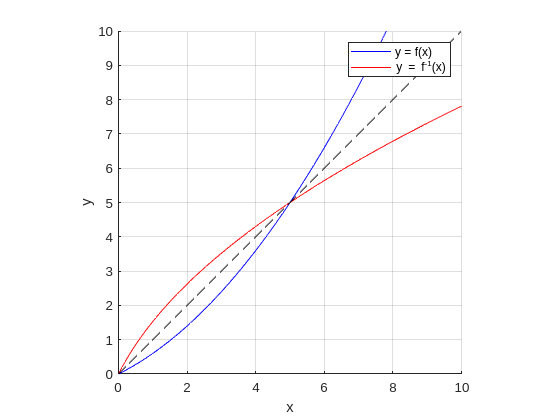

% Inverse (radius to current)
f_x_inv = @(x) (x./a + (b/(2*a))^2 - c/a).^(1/2) - (b/(2*a));

% Plot 
figure();
hold on; grid on;
plot(x, f_x(x), 'blue')
plot(x, f_x_inv(x), 'red')
plot([0 10], [0 10], 'k--')
xlabel('x')
ylabel('y')
axis([0 10 0 10])
axis square
legend({'y = f(x)', 'y = f^{-1}(x)'})